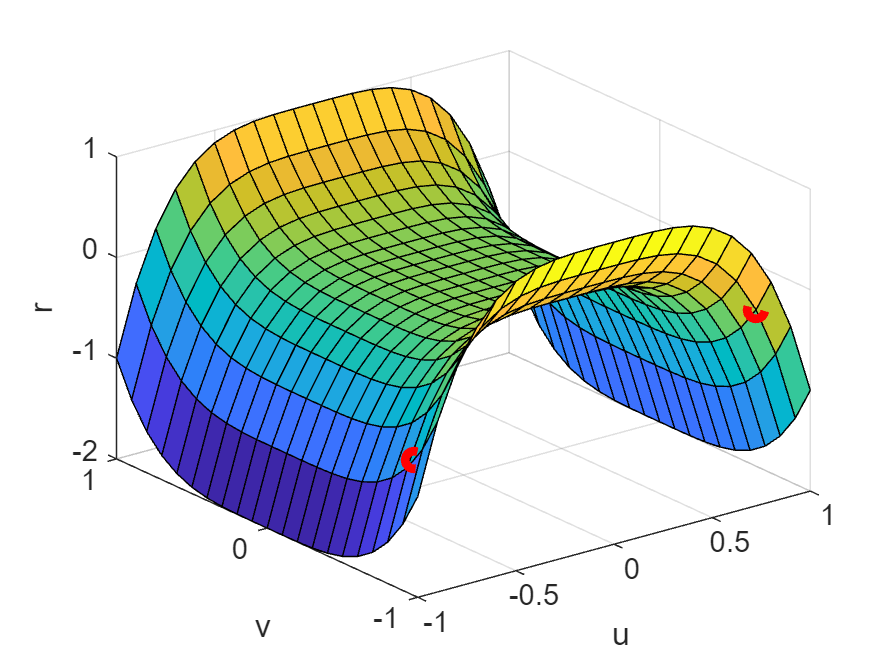

u = -1:0.1:1;
v = [-1:0.1:1]';
r_func = @(u,v) v.^4-2.*u.^4;
r = r_func(u,v);

f1 = figure;
figure(f1);
surf(u,v,r)
xlabel("u")
ylabel("v")
zlabel("r")
hold on
plot3(-0.9,-0.85, r_func(-0.9, -0.85), 'or','LineWidth',3)
plot3(0.8,-0.9, r_func(0.8, -0.9), 'or','LineWidth',3)
hold off

a = -0.9

a = -0.9000

alpha = -0.85

alpha = -0.8500

b = 0.8

b = 0.8000

beta = -0.9

beta = -0.9000


umesh = linspace(-0.9, 0.8, 10);
solinit = bvpinit(umesh, [0; 1]);

sol4c = bvp5c(@bvpfcn, @bcfcn, solinit)

sol4c = struct with fields:
    solver: 'bvp5c'
         x: [-0.9000 -0.8895 -0.8790 -0.8685 -0.8580 -0.8475 -0.8370 -0.8213 -0.8056 -0.7898 -0.7741 -0.7601 -0.7461 -0.7338 -0.7216 -0.7059 -0.6901 -0.6744 -0.6586 -0.6429 -0.6272 -0.6114 -0.5957 -0.5799 -0.5642 -0.5485 -0.5327 … ] (1×112 double)
         y: [2×112 double]
     idata: [1×1 struct]
     stats: [1×1 struct]


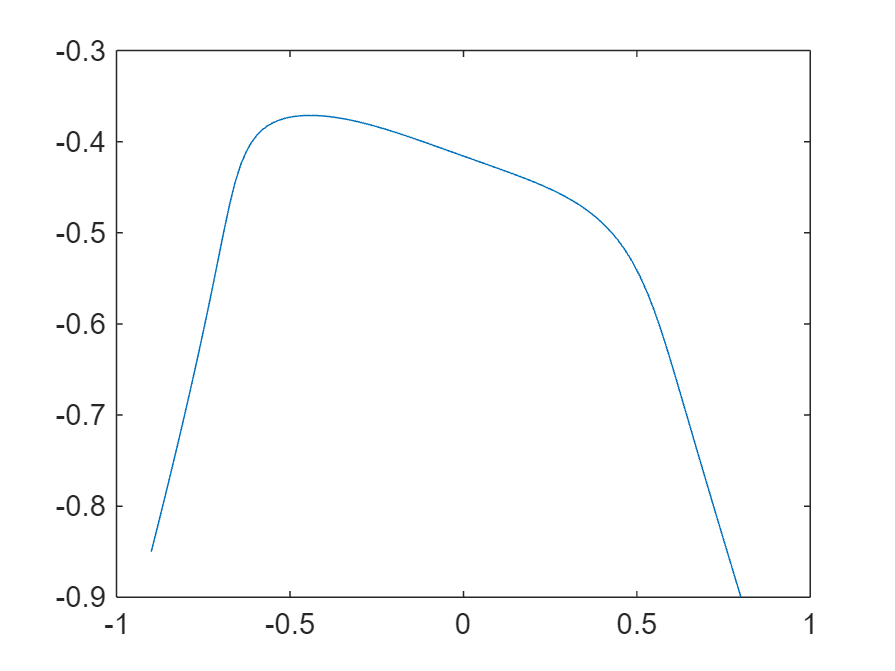


f2 = figure;
figure(f2)
plot(sol4c.x,sol4c.y(1,:))

%legend('1','2')

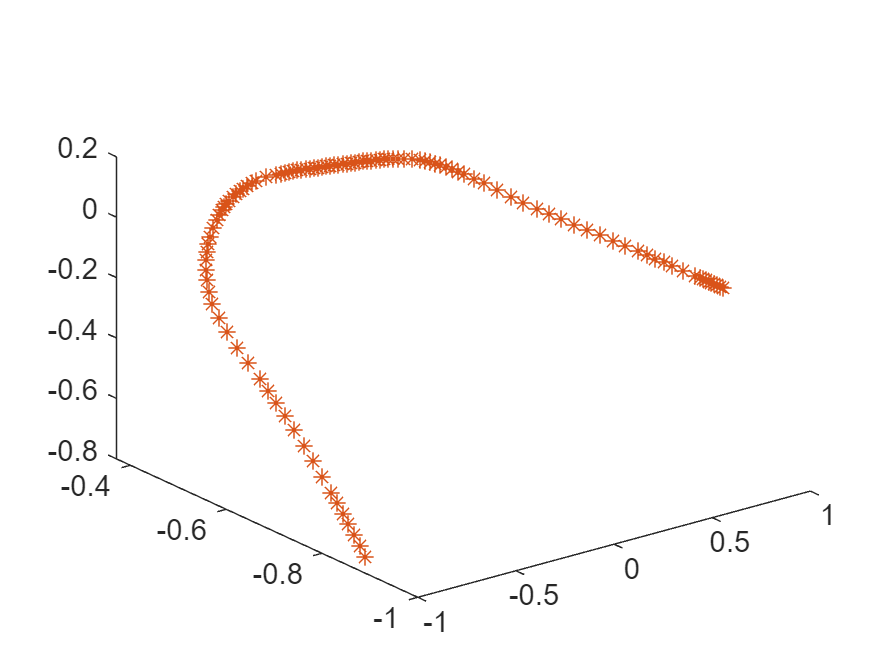


figure(f1);
hold on
plot3(sol4c.x,sol4c.y(1,:),r_func(sol4c.x,sol4c.y(1,:)), '*')
hold off

function res = bcfcn(Va,Vb)
res = [Va(1)+0.85
       Vb(1)+0.9];
end

function dVdu = bvpfcn(u,V)
dVdu = [V(2)
       48*(V(1)^3+2*u^3*V(2))*(2*u^2-V(1)^2*V(2)^2)];
end